clear all
L1=4

L1 = 4

L2=3

L2 = 3

L3=2

L3 = 2

link0=Link('d',0,'a',0,'alpha',0,'modified')  % a0=0, alpha0=0, d1=0, theta1

 
link0 = 
Revolute(mod): theta=q, d=0, a=0, alpha=0, offset=0


link1=Link('d',0,'a',4,'alpha',0,'modified')  % a1=4, alpha1=0, d2=0, theta2

 
link1 = 
Revolute(mod): theta=q, d=0, a=4, alpha=0, offset=0


link2=Link('d',0,'a',3,'alpha',0,'modified')  % a2=3, alpha2=0, d3=0, theta3

 
link2 = 
Revolute(mod): theta=q, d=0, a=3, alpha=0, offset=0


link3=Link('d',0,'a',2,'alpha',0,'modified')  % a3=2, alpha3=0, d4=0, theta_H=0

 
link3 = 
Revolute(mod): theta=q, d=0, a=2, alpha=0, offset=0


manipulator=SerialLink([link0 link1 link2 link3],'name','manipulator')

 
manipulator = 
 
manipulator:: 4 axis, RRRR, modDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|          0|          4|          0|          0|
|  3|         q3|          0|          3|          0|          0|
|  4|         q4|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


% check Jacobian_initial
theta1=pi/18;
theta2=pi/9;
theta3=pi/6;
theta_H=0;
J=[-L1*sin(theta1)-L2*sin(theta1+theta2)-L3*sin(theta1+theta2+theta3) -L2*sin(theta1+theta2)-L3*sin(theta1+theta2+theta3) -L3*sin(theta1+theta2+theta3);
    L1*cos(theta1)+L2*cos(theta1+theta2)+L3*cos(theta1+theta2+theta3)  L2*cos(theta1+theta2)+L3*cos(theta1+theta2+theta3)  L3*cos(theta1+theta2+theta3);
    1                                                                  1                                                   1]

J =    -3.9266   -3.2321   -1.7321
    7.5373    3.5981    1.0000
    1.0000    1.0000    1.0000


manipulator.jacob0([theta1 theta2 theta3 theta_H])

ans =    -3.9266   -3.2321   -1.7321         0
    7.5373    3.5981    1.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


% check Jacobian_final
theta1=0.23;
theta2=0.26;
theta3=0.44;
theta_H=0;
J=[-L1*sin(theta1)-L2*sin(theta1+theta2)-L3*sin(theta1+theta2+theta3) -L2*sin(theta1+theta2)-L3*sin(theta1+theta2+theta3) -L3*sin(theta1+theta2+theta3);
    L1*cos(theta1)+L2*cos(theta1+theta2)+L3*cos(theta1+theta2+theta3)  L2*cos(theta1+theta2)+L3*cos(theta1+theta2+theta3)  L3*cos(theta1+theta2+theta3);
    1                                                                  1                                                   1]

J =    -3.9270   -3.0151   -1.6032
    7.7373    3.8427    1.1957
    1.0000    1.0000    1.0000


manipulator.jacob0([theta1 theta2 theta3 theta_H])

ans =    -3.9270   -3.0151   -1.6032         0
    7.7373    3.8427    1.1957         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


% Animation
M=zeros(51,4)

M =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


sim('MATLAB_Exercise_5a')

x =
    7.5373

y =
    3.9266

X =
    7.5373
    3.9266
    1.0472

L1 =
     4

L2 =
     3

L3 =
     2

theta1 =
    0.1745

theta2 =
    0.3491

theta3 =
    0.5236

THETA_dot_C =
   -0.1292
    0.2867
   -0.3574

det_J =
    4.1042

tau =
   14.1480
    6.9641
    3.2679

x =
    7.5471

y =
    3.9115

X =
    7.5471
    3.9115
    1.0372

L1 =
     4

L2 =
     3

L3 =
     2

theta1 =
    0.1681

theta2 =
    0.3634

theta3 =
    0.5057

THETA_dot_C =
   -0.1220
    0.2706
   -0.3486

det_J =
    4.2654

tau =
   14.1827
    6.9645
    3.3126

x =
    7.5525

y =
    3.9043

X =
    7.5525
    3.9043
    1.0322

L1 =
     4

L2 =
     3

L3 =
     2

theta1 =
    0.1654

theta2 =
    0.3694

theta3 =
    0.4975

THETA_dot_C =
   -0.1189
    0.2639
   -0.3450

det_J =
    4.3322

tau =
   14.2007
    6.9684
    3.3349

x =
    7.5573

y =
    3.8966

X =
    7.5573
    3.8966
    1.0272

L1 =
     4

L2 =
     3

L3 =
     2

theta1 =
    0.1623

theta2 =
    0.3762

theta3 =


M(:,1:3)=Theta_all

M =     0.1745    0.3491    0.5236         0
    0.1623    0.3762    0.4887         0
    0.1513    0.4006    0.4553         0
    0.1414    0.4228    0.4231         0
    0.1323    0.4430    0.3919         0
    0.1241    0.4616    0.3616         0
    0.1165    0.4786    0.3321         0
    0.1096    0.4943    0.3033         0
    0.1033    0.5087    0.2752         0
    0.0975    0.5220    0.2476         0


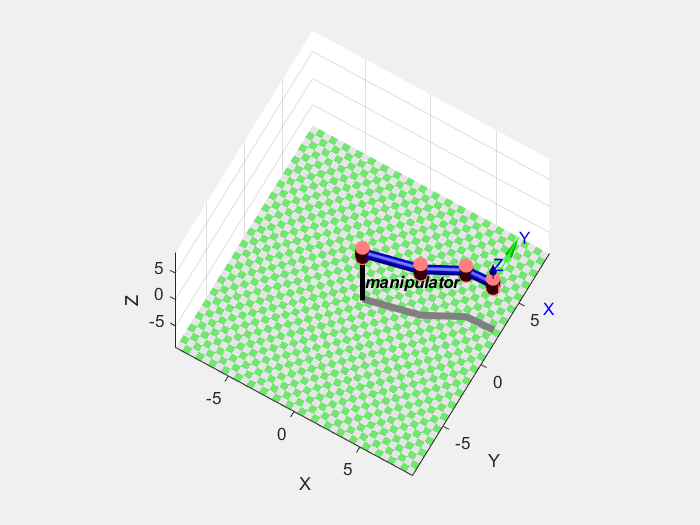

manipulator.plot(M,'delay',0.1)